T

T = 4×2 table
                Range       Nominal
             ___________    _______

    S0       100    3000      1550 
    I0         1     500     250.5 
    beta       0       1       0.5 
    gamma      0       1       0.5 


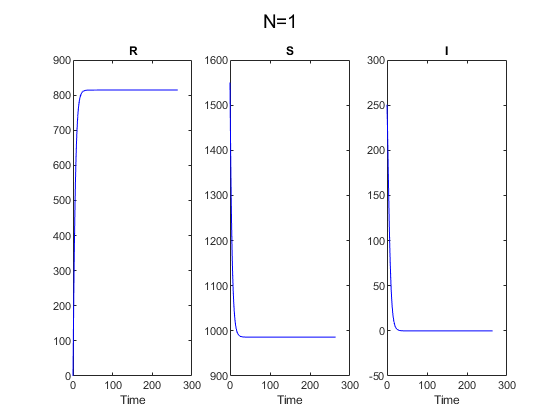

ans = 	1.0e+03 *

         0    0.1204    0.2297    0.3266    0.4108    0.4827    0.5434    0.5941    0.6359    0.6703    0.6985    0.7212    0.7396    0.7543    0.7663    0.7759    0.7836    0.7898    0.7947    0.7987    0.8018    0.8044    0.8064    0.8080    0.8093    0.8103    0.8111    0.8118    0.8123    0.8127    0.8131    0.8133    0.8136    0.8137    0.8139    0.8140    0.8140    0.8141    0.8142    0.8142    0.8142    0.8143    0.8143    0.8143    0.8143    0.8143    0.8144    0.8144    0.8144    0.8144
    1.5500    1.4497    1.3644    1.2929    1.2338    1.1855    1.1462    1.1144    1.0888    1.0682    1.0516    1.0384    1.0279    1.0196    1.0128    1.0074    1.0031    0.9997    0.9969    0.9947    0.9930    0.9916    0.9905    0.9896    0.9889    0.9883    0.9879    0.9875    0.9872    0.9870    0.9868    0.9867    0.9866    0.9865    0.9864    0.9863    0.9863    0.9863    0.9862    0.9862    0.9862    0.9862    0.9862    0.9862    0.9861    0.9861    0.9861    0.9861 

T.Properties.CustomProperties.output=1:3;
gsua_eval(T.Nominal,T)

M=gsua_dmatrix(T,1000,'Show','off','Method','Sobol');

T.Properties.CustomProperties.output=3;
T=gsua_sa(M,T,'parallel',false);

Progress: 17%
Estimated processing time (h:m:s): 0:0:1
Remaining time (h:m:s): 0:0:1
Elapsed time (h:m:s): 0:0:0
Estimated stop time (h:m:s): 14:58:49
Number of simulations: 300
Progress: 34%
Estimated processing time (h:m:s): 0:0:1
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:0:0
Estimated stop time (h:m:s): 14:58:49
Number of simulations: 300
Progress: 50%
Estimated processing time (h:m:s): 0:0:1
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:0:0
Estimated stop time (h:m:s): 14:58:49
Number of simulations: 300
Progress: 67%
Estimated processing time (h:m:s): 0:0:1
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:0:0
Estimated stop time (h:m:s): 14:58:49
Number of simulations: 300
Progress: 84%
Estimated processing time (h:m:s): 0:0:1
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:0:1
Estimated stop time (h:m:s): 14:58:49
Number of simulations: 300
Progress: 100%
Estimated processing time (h:m:s): 0:0:1
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:

T

T = 4×6 table
                Range       Nominal       Si          STi         STi_vec            Si_vec    
             ___________    _______    _________    _______    ______________    ______________

    S0       100    3000      1550      0.053473    0.22495    [1×265 double]    [1×265 double]
    I0         1     500     250.5      0.034693    0.24178    [1×265 double]    [1×265 double]
    beta       0       1       0.5      0.025732    0.26053    [1×265 double]    [1×265 double]
    gamma      0       1       0.5     -0.066033     1.6077    [1×265 double]    [1×265 double]


sum(T.STi), sum(T.Si)

ans = 2.3350

ans = 0.0479

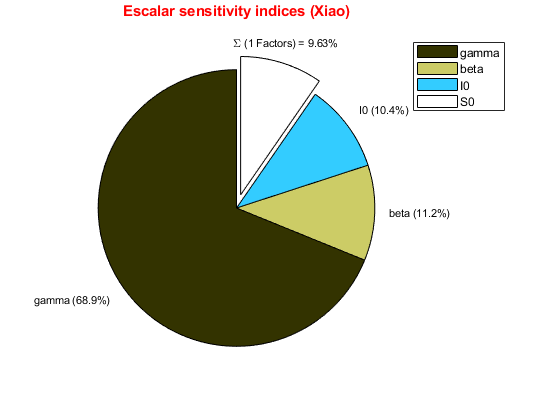

gsua_plot('Pie',T,T.STi);

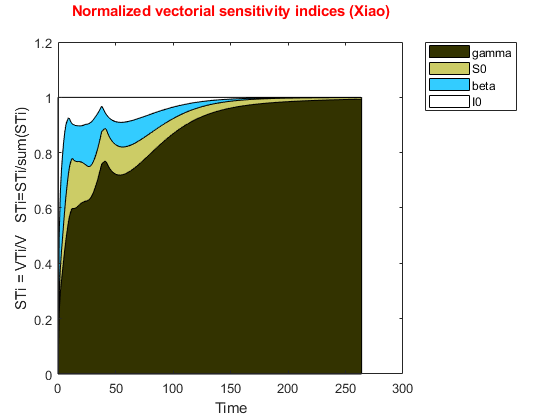

gsua_plot('TotalSensitivityArea',T,T.STi_vec,0:264);

help gsua_sa

  Function for sensitivity analysis
 
  T=gsua_sa(M,T)
  Parameters:
  M <-- design matrix from gsua_dmatrix function
  T <-- summary table from gsua_dataprep function
  Output:
  T <-- summary table with sensitivity indices.
  Additional features:
  It is possible to request 2 extra positional outputs:
  J <-- vector of model outputs in scalar representation (MSE)
  Y <-- model output matrix (same as gsua_ua output)
  It is possible to choose between 6 SA methods using the paired feature
  'SensMethod',method. Where method is one of the following:
  'Saltelli'    <-- requires N*(Np/2+1) simulations
  'Jansen'      <-- requires N*(Np/2+1) simulations
  'Xiao'        <-- newest method (Default), requires N*(Np/2+1)
                    simulations
  'Sobol'       <-- classic method, requires N*(Np+1) simulations
  'brute-force' <-- explores all possible combinations, N + Np2*N^2
                    simulations
  'OAT'         <-- non-global method, requires N*(Np+1) simu

help gsua_pe

  Parameter estimation function
  [T,res] = gsua_pe(T,xdata,ydata,N)
  Parameters:
  T     <-- summary table from gsua_dataprep function
  xdata <-- array of points where the model will be evaluated
  ydata <-- array with expected model output
  Outputs:
  T   <-- summary table with parameter estimation results
  res <-- cost functions for each estimation
  Additional paired features:
  'N',N     <-- number of parameter estimations
  'Multistart',k <-- activate multistart feature for lsqcurvefit optimizer,
  perform k parameter estimations in each cycle
  'solver',{'lsqc','lsqn','ga','particle','psearch','surrogate','annealing'}
  <-- allows to choose among several matlab optimizers. Default: lsqc
  'opt',optimoptions(optimizer,...) <-- allows to configure the respective
  matlab optimizer, optimizer must match with the real matlab optimizer
  name.
  'ipoint',point <-- allows to give to the optimizer the initial points for
  estimations. point must have the same numbe

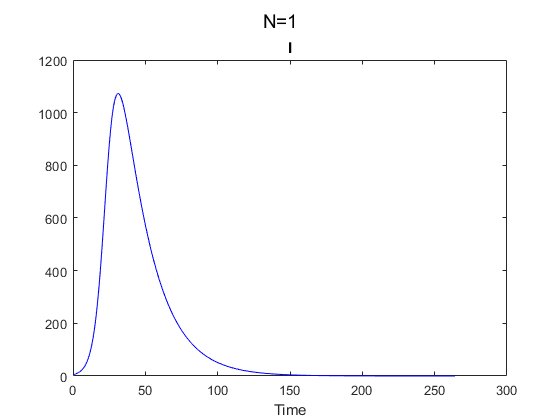

Y=gsua_eval([2e3 5 0.3 0.05]',T);

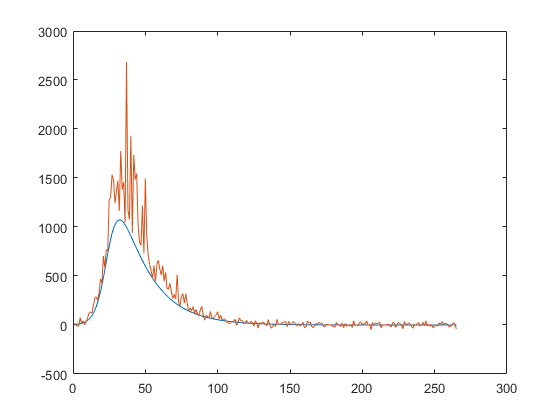

noise=normrnd(0,20,1,265);
yexp=Y+noise+abs(Y.*normrnd(0,0.5,1,265));
figure(1)
clf
plot(Y)
hold on
plot(yexp)

solver='lsqc';%this is the default solver
xdata=0:264;
opt=optimoptions('lsqcurvefit','UseParallel',false);%configure optimizer
[T,res]=gsua_pe(T,xdata,yexp,'solver',solver,'Show','on','opt',opt,'N',50);

T

T = 4×7 table
                Range       Nominal       Si          STi         STi_vec            Si_vec           Estlsqc   
             ___________    _______    _________    _______    ______________    ______________    _____________

    S0       100    3000      1550      0.053473    0.22495    [1×265 double]    [1×265 double]    [1×10 double]
    I0         1     500     250.5      0.034693    0.24178    [1×265 double]    [1×265 double]    [1×10 double]
    beta       0       1       0.5      0.025732    0.26053    [1×265 double]    [1×265 double]    [1×10 double]
    gamma      0       1       0.5     -0.066033     1.6077    [1×265 double]    [1×265 double]    [1×10 double]


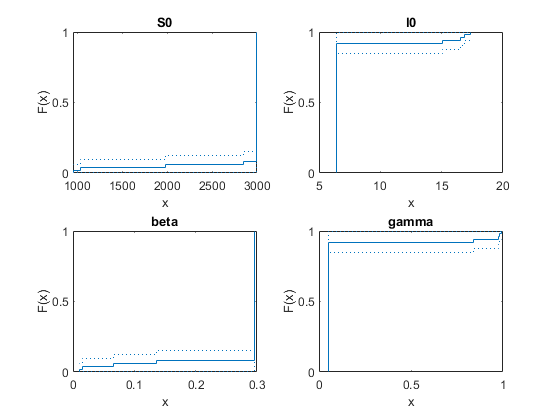

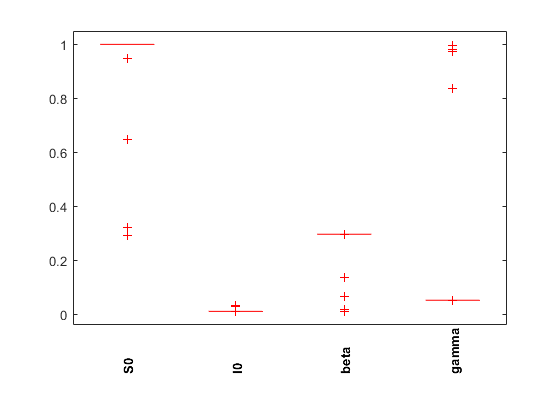

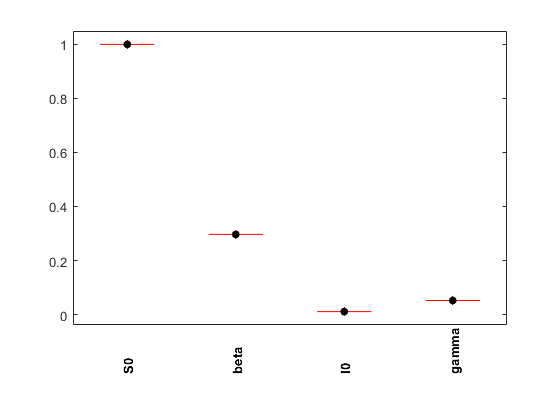

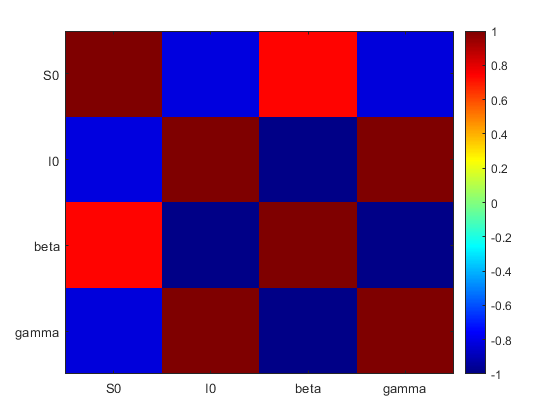

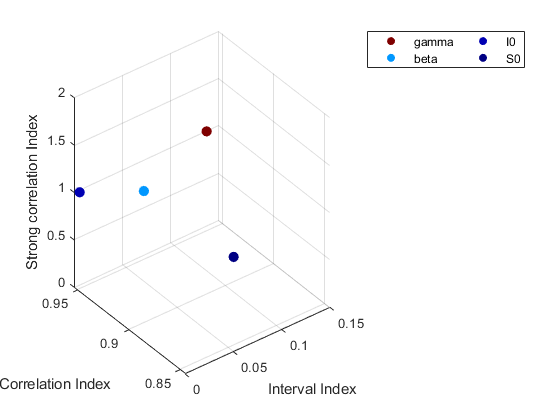

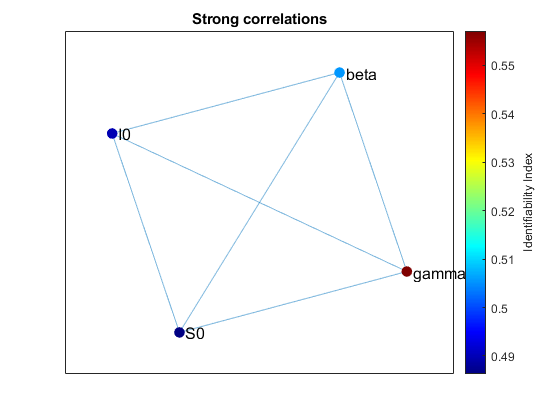

T = 4×9 table
                   Range           Nominal        Si          STi         STi_vec            Si_vec           Estlsqc            Est          index 
             __________________    ________    _________    _______    ______________    ______________    _____________    _____________    _______

    S0        2854.4       3000        3000     0.053473    0.22495    [1×265 double]    [1×265 double]    [1×50 double]    [1×50 double]    0.48628
    I0        5.4685      7.384      6.4263     0.034693    0.24178    [1×265 double]    [1×265 double]    [1×50 double]    [1×50 double]     0.4898
    beta     0.27326    0.31993 

Tia=gsua_ia(T,T.Estlsqc,true,false,true);

Progress: 100%
Estimated processing time (h:m:s): 0:0:0
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:0:0
Estimated stop time (h:m:s): 15:35:46
Number of simulations: 100


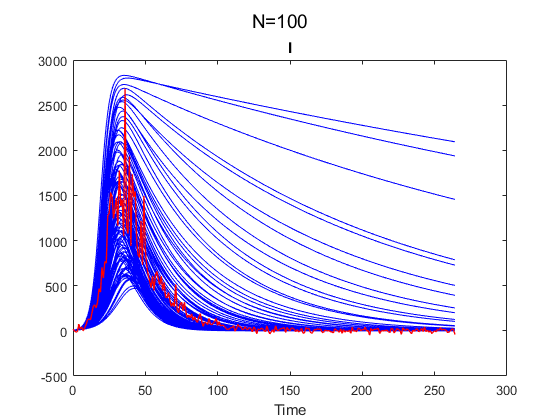

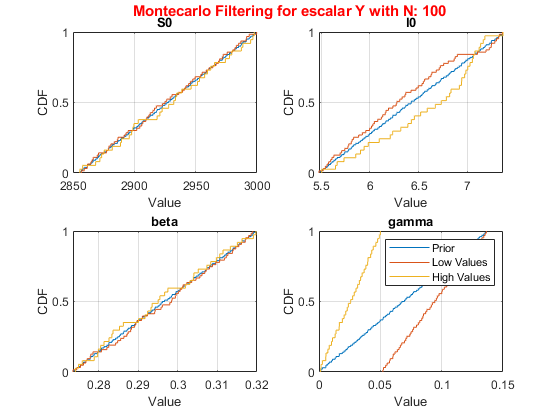

M2=gsua_dmatrix(Tia,100);
gsua_ua(M2,Tia,'xdata',xdata,'ynom',yexp,'parallel',false);